clear all; close all;clear clc;

% Input modulus of elasticity and posson ratio
E0=2.574e10; %modulus of elasticity (Pa)
v=0.2;     %posson ratio 
g=-9.81;  %gravitational acceleration
SigmaMax= 30*10^6 %(Pa)

SigmaMax = 30000000

p = 2400; %kg/m3 density of concrete

% Input The cartesian coordinate for Tetrahedron with four nodes
%Uses pre-created mesh from gmsh
%Run mesh file name without .m:
%tetra_size_one   % Name of the file without .m exported from Gmsh
XYZCoord = [0 0 0.00; 0.25 0 0.00; 0.25 0.25 0.00; 0 0.25 0.00;
            0 0 0.25; 0.25 0 0.25; 0.25 0.25 0.25; 0 0.25 0.25;
            0 0 0.50; 0.25 0 0.50; 0.25 0.25 0.50; 0 0.25 0.50;
            0 0 0.75; 0.25 0 0.75; 0.25 0.25 0.75; 0 0.25 0.75;
            0 0 1.00; 0.25 0 1.00; 0.25 0.25 1.00; 0 0.25 1.00;
            0 0 1.25; 0.25 0 1.25; 0.25 0.25 1.25; 0 0.25 1.25;
            0 0 1.50; 0.25 0 1.50; 0.25 0.25 1.50; 0 0.25 1.50;
            0 0 1.75; 0.25 0 1.75; 0.25 0.25 1.75; 0 0.25 1.75;
            0 0 2.00; 0.25 0 2.00; 0.25 0.25 2.00; 0 0.25 2.00;
            0 0 2.25; 0.25 0 2.25; 0.25 0.25 2.25; 0 0.25 2.25;
            0 0 2.50; 0.25 0 2.50; 0.25 0.25 2.50; 0 0.25 2.50;
            0 0 2.75; 0.25 0 2.75; 0.25 0.25 2.75; 0 0.25 2.75;
            0 0 3.00; 0.25 0 3.00; 0.25 0.25 3.00; 0 0.25 3.00];


xp = XYZCoord(:,1)'; % [Node1 Node2 Node3 Node4 ]
yp = XYZCoord(:,2)'; % [Node1 Node2 Node3 Node4 ]
zp = XYZCoord(:,3)'; % [Node1 Node2 Node3 Node4 ]

ELEMCon=[1 2 3 4 5 6 7 8;
           5 6 7 8 9 10 11 12;
           9 10 11 12 13 14 15 16;
           13 14 15 16 17 18 19 20;
           17 18 19 20 21 22 23 24;
           21 22 23 24 25 26 27 28;
           25 26 27 28 29 30 31 32;
           29 30 31 32 33 34 35 36;
           33 34 35 36 37 38 39 40;
           37 38 39 40 41 42 43 44;
           41 42 43 44 45 46 47 48;
           45 46 47 48 49 50 51 52]; %element connectivity
NE=size(ELEMCon,1);                %Number of elements
nNode=size(XYZCoord,1);                  %Number of nodes
nDof=nNode*3;                         %Total number degree of freedom

% Plot the tetrahedron using tetramesh
%tetramesh(ELEMCon, coor);

% Customize the plot (optional)
% xlabel('X-axis');
% ylabel('Y-axis');
% zlabel('Z-axis');
% title('Tetrahedron');
%-------------------NODE container and ELEMENT container--------------------
for p=1:nNode
    NODE(p).X=xp(1,p);NODE(p).Y=yp(1,p);NODE(p).Z=zp(1,p);
end

for eNo=1:NE
    ELEMENT(eNo).con=ELEMCon(eNo,:);
end
%-------------------Input support matrix and Load matrix--------------------
%[ Node ux uy uz]          ux=1 Fixed ;ux=0 Free
support=[1 1 1 1; %[ Node ux uy uz] 
         2 1 1 1; % ux=1 Fixed ;ux=0 Free
         3 1 1 1;
         4 1 1 1];
nSupport=size(support,1);

%IN put Load conditions [Node Fx Fy Fz]
load=[50 -300000/2 0 0;
      51 -300000/2 0 0];
nLoad=size(load,1);

%INput direction of force 2=X-direction ;3=Y-direction ;4=Z-direction 
F_Location=2

F_Location = 2


%INput Degree of freedome direction of interest to plot curve Force-Displacement
dof_direction=[3*load(1,1)-2;
               3*load(2,1)-2] 

dof_direction =    148
   151



%Shape Function
syms zeta xi eta
N1 = 1/8 * (1+xi)*(1+eta)*(1-zeta);
N2 = 1/8 * (1-xi)*(1+eta)*(1-zeta);
N3 = 1/8 * (1-xi)*(1-eta)*(1-zeta);
N4 = 1/8 * (1+xi)*(1-eta)*(1-zeta);
N5 = 1/8 * (1+xi)*(1+eta)*(1+zeta);
N6 = 1/8 * (1-xi)*(1+eta)*(1+zeta);
N7 = 1/8 * (1-xi)*(1-eta)*(1+zeta);
N8 = 1/8 * (1+xi)*(1-eta)*(1+zeta);

N=[N1 N2 N3 N4 N5 N6 N7 N8];
nN=length(N);

%To check the volume of strucutre
V_Ele=zeros(1,NE);

%Preparing to store each stiffness element in 3D matrix
kElem=zeros(24,24,NE);
for eNo=1:NE
    ELEMENT(eNo).Ex=E0;
    ELEMENT(eNo).Ey=E0;
    ELEMENT(eNo).Ez=E0;
    ELEMENT(eNo).Exy=E0;
    ELEMENT(eNo).Eyz=E0;
    ELEMENT(eNo).Exz=E0;
end

%% INCREMENTAL Steps

uDisp=zeros(nDof,1);
NINC=10;                      %the number of calculation steps applied
uDel_inc=zeros(NINC,(nLoad));
uLoad_inc=zeros(NINC,nLoad);

for nin=1:NINC
    tic
for eNo=1:NE

    % Element Coordinates
    for i = 1:nN
        xp(i) = XYZCoord(ELEMCon(eNo,i),1); 
        yp(i) = XYZCoord(ELEMCon(eNo,i),2);
        zp(i) = XYZCoord(ELEMCon(eNo,i),3);
        ELEMENT(eNo).X(i) = NODE(ELEMENT(eNo).con(i)).X;
        ELEMENT(eNo).Y(i) = NODE(ELEMENT(eNo).con(i)).Y;
        ELEMENT(eNo).Z(i) = NODE(ELEMENT(eNo).con(i)).Z;
    end

    % Coordinate Mapping
    x=0; y=0; z=0;
    for i=1:nN
    x=x+xp(i)*N(i);
    y=y+yp(i)*N(i);
    z=z+zp(i)*N(i);
    end

    % Jacobian
    J = [diff(x,xi) diff(y,xi) diff(z,xi);
        diff(x,eta) diff(y,eta) diff(z,eta);
        diff(x,zeta) diff(y,zeta) diff(z,zeta)];

    % Differentiating the N matrix to get doMat, dN
    for i = 1:nN
    dN(:,i) = inv(J) * [diff(N(i),xi);
                        diff(N(i),eta);
                        diff(N(i),zeta)];
    end

    % Arranging the terms to get the B matrix
    B = sym(zeros(6,nN*3));
    for i = 1:nN
        j = 3*i - 2;
        k = 3*i;
        B(1:6, j:k) = [dN(1,i), 0, 0; 
                      0, dN(2,i), 0;
                      0, 0, dN(3,i);
                      dN(2,i), dN(1,i), 0;
                      0, dN(3,i), dN(2,i);
                      dN(3,i), 0, dN(1,i)];
    end
    ELEMENT(eNo).B=B;

    % Define constitutive matrix (D)
 % Elasticity matrix D
    d =(1+v)*(1-2*v);
    D = 1/d*[ELEMENT(eNo).Ex*(1-v) ELEMENT(eNo).Ey*v ELEMENT(eNo).Ez*v 0 0 0;
              ELEMENT(eNo).Ex*v ELEMENT(eNo).Ey*(1-v) ELEMENT(eNo).Ez*v 0 0 0;
              ELEMENT(eNo).Ex*v ELEMENT(eNo).Ey*v ELEMENT(eNo).Ez*(1-v) 0 0 0;
              0 0 0 ELEMENT(eNo).Exy*(1-2*v)/2 0 0;
              0 0 0 0 ELEMENT(eNo).Eyz*(1-2*v)/2 0;
              0 0 0 0 0 ELEMENT(eNo).Exz*(1-2*v)/2];

    % Mass Matrix (M)
    H = sym(zeros(3,nN*3));
    for i = 1 : nN
        j = 3*i-2; 
        k = 3*i;
        H(:,j:k) = [N(i), 0, 0;
                      0, N(i), 0;
                      0, 0, N(i)];
    end


 % Integrand is (for Stiffness)
    f1= B'*D*B*det(J);
    
    % Direct Integration option 1: Direct Stiffness method
    %ELEMENT(i).stiffness = int(int(int(f1, xi, -1,1), eta, -1,1), zeta, -1,1);

    %Gauss Points
[xg,wg]=lgwt(2,-1,1);
element_stiffness=...
    wg(1)*wg(1)*wg(1)*subs(f1,[xi,eta,zeta],[xg(1),xg(1),xg(1)]) + ...
    wg(2)*wg(1)*wg(1)*subs(f1,[xi,eta,zeta],[xg(2),xg(1),xg(1)]) + ...
    wg(2)*wg(1)*wg(2)*subs(f1,[xi,eta,zeta],[xg(2),xg(1),xg(2)]) + ...
    wg(1)*wg(1)*wg(2)*subs(f1,[xi,eta,zeta],[xg(1),xg(1),xg(2)]) + ...
    wg(1)*wg(2)*wg(1)*subs(f1,[xi,eta,zeta],[xg(1),xg(2),xg(1)]) + ...
    wg(2)*wg(2)*wg(1)*subs(f1,[xi,eta,zeta],[xg(2),xg(2),xg(1)]) + ...
    wg(2)*wg(2)*wg(2)*subs(f1,[xi,eta,zeta],[xg(2),xg(2),xg(2)]) + ...
    wg(1)*wg(2)*wg(2)*subs(f1,[xi,eta,zeta],[xg(1),xg(2),xg(2)]);

     ELEMENT(i).stiffness = eval(element_stiffness);

end

%To counter check the negative stiffness effect by measuring the total
%volume of structure 
V_Ele;      %negative value indicates flipping of element, require reordering of nodes
Total_volume = sum(V_Ele);
%-------------------------------------------------------------------------%
%                  Global Stiffness Matrix Calculation                    %
%-------------------------------------------------------------------------%
% This part calculates the global stiffness matrix. Basically; for each
% element it takes 4x4 part from the element stiffness matrix and puts to
% the correct spot on the global stiffness matrix. This process loops until
% all elements all parts placed in to the global stiffness matrix.
KG = zeros(nDof,nDof);

for eNo=1:NE
    kElem = ELEMENT(i).stiffness;
    for j=1:nN
        for i=1:nN
            n = ELEMCon(eNo,i);
            m = ELEMCon(eNo,j);
            KG(3*n-2,3*m-2) = KG(3*n-2,3*m-2)+kElem(3*i-2,3*j-2);              %K11
            KG(3*n-2,3*m-1) = KG(3*n-2,3*m-1)+kElem(3*i-2,3*j-1);              %K12
            KG(3*n-2,3*m) = KG(3*n-2,3*m)+kElem(3*i-2,3*j);                    %K13
            KG(3*n-1,3*m-2) = KG(3*n-1,3*m-2)+kElem(3*i-1,3*j-2);              %K21
            KG(3*n-1,3*m-1) = KG(3*n-1,3*m-1)+kElem(3*i-1,3*j-1);              %K22
            KG(3*n-1,3*m) = KG(3*n-1,3*m)+kElem(3*i-1,3*j);                    %K23
            KG(3*n,3*m-2) = KG(3*n,3*m-2)+kElem(3*i,3*j-2);                    %K13
            KG(3*n,3*m-1) = KG(3*n,3*m-1)+kElem(3*i,3*j-1);                    %K23
            KG(3*n,3*m) = KG(3*n,3*m)+kElem(3*i,3*j);                          %K33
        end
    end
end
KG;

%-------------------------------------------------------------------------%
%           Apply Support Conditions to the Global Stiffnes Matrix        %
%-------------------------------------------------------------------------%
% This part makes zeros all columns and rows where the supports are except
% the diagonal element of the matrix. Diagonal element set to 1. I choose
% this method because with this way sort of displacement evaulated are not
% changes. And later it is easier to use evaluated values. Only negative
% side of this approach is we have to be careful not to put force where the
% support is fixed.
for i=1:nSupport
    n = support(i,1);
    if (support(i,2) == 1) %%%ux =0
        KG(3*n-2,:) = 0;
        KG(:,3*n-2) = 0;
        KG(3*n-2,3*n-2) = 1;
    end
    if (support(i,3) == 1) %%%uy=0
        KG(3*n-1,:) = 0;
        KG(:,3*n-1) = 0;
        KG(3*n-1,3*n-1) = 1;
    end
    if   (support(i,4) == 1) %%%uz=0
        KG(3*n,:) = 0;
        KG(:,3*n) = 0;
        KG(3*n,3*n) = 1;
    end
end

KG;

%-------------------------------------------------------------------------%
%                       Load Vector Computation                           %
%-------------------------------------------------------------------------%
% In this part load traction vector created. If there is a load vector get the value
% from load matrix. If not not load value set to zero.
f_trac = zeros(nDof,1);
for i=1:nLoad
    n = load(i,1);
    f_trac(3*n-2) = load(i,2)/NINC;
    f_trac(3*n-1) = load(i,3)/NINC;
    f_trac(3*n) = load(i,4)/NINC;
end


%Body force applied at each node in z-axis
% f_body = zeros(nDof,1);
% for eNo=1:NE
%         for i=1:nN
%             n = ELEMCon(eNo,i);
%             f_body(3*n,1) = (f_body(3*n,1)+g*p*30/4)/NINC;
%         end
% end
fvec = f_trac;


% uDel_inc=KG\f_trac
uDisp= uDisp + KG\f_trac;

%uDel_inc =zeros(ninc,(nLoad))
    for q=1:(nLoad)          % Display all displacements on the free end
    %    fprintf('%10.7f \n',uDisp(load(i,1)*2));
        uDel_inc(nin,q)=uDisp(load(q,1)*3-2,1);
        if(nin==1)
            uLoad_inc(nin,q)=fvec(load(q,1)*3-2);
        else
            uLoad_inc(nin,q)=uLoad_inc(nin-1,q)+fvec(load(q,1)*3-2);
        end
    end
 %Calculation of stresses
    
    %Nodal displacements
    for i=1:nNode
        NODE(i).u=[uDisp(3*i-2); uDisp(3*i-1);uDisp(3*i)];
    end
    %Element displacements
    for i=1:NE
        temp=[];
        for j=1:nN
            temp=[temp;
                  NODE(ELEMCon(i,j)).u];
        end
                ELEMENT(i).u=temp;
    end
    %Element Stresses
    for i=1:NE
       uelem = ELEMENT(i).u;                                                % Retrieve the displacement vector for element 'i'
       Belem=ELEMENT(i).B;                                                  % Retrieve the B matrix for element 'i'
       sigma = D*Belem*uelem;                                               % Calculate stress using Hooke's law: stress = D * B * u            
       strain=Belem*uelem;                                                  % Calculate strain: strain = B * u
       %Element Stresses
SCP = [-1 -1 1; 1 -1 1 ; 1 1 1 ; -1 1 1 ; -1 1 1; -1 1 1; -1 1 1; -1 1 1];
  for j=1:8
       ELEMENT(i).sigma(:,j) =double(subs(sigma,[xi,eta,zeta],SCP(j,:))) ;
       ELEMENT(i).strain(:,j) =double(subs(strain,[xi,eta,zeta],SCP(j,:))) ;
   end
    
       Strain_x=mean(ELEMENT(i).strain(1,:));                               % Calculate the mean strain in the x-direction for the ith element
       Stress_x=mean(ELEMENT(i).sigma(1,:));                                % Calculate the mean stress in the x-direction for the ith element
       [Stress, Stiffness]=GetHDStressStiffness(E0,SigmaMax,abs(Strain_x)); % Call the function GetHDStressStiffness to obtain the stress and stiffness for the material based on certain parameters (E0, SigmaMax, and the absolute value of Strain_x)
       ELEMENT(i).Actual_stress_x=Stress*sign(Strain_x);                    % Calculate the actual stress in the x-direction for the ith element,considering the sign of Strain_x
       ELEMENT(i).Ex=Stiffness;                                             % Assign the stiffness obtained from the function to the property Ex of the ith element

       Strain_y=mean(ELEMENT(i).strain(2,:));                               % Calculate the mean strain in the y-direction for the ith element
       Stress_y=mean(ELEMENT(i).sigma(2,:));                                % Calculate the mean stress in the y-direction for the ith element
       [Stress, Stiffness]=GetHDStressStiffness(E0,SigmaMax,abs(Strain_y)); % Call the function GetHDStressStiffness to obtain the stress and stiffness for the material based on certain parameters (E0, SigmaMax, and the absolute value of Strain_y)
       ELEMENT(i).Actual_stress_y=Stress*sign(Strain_y);                    % Calculate the actual stress in the y-direction for the ith element,considering the sign of Strain_y
       ELEMENT(i).Ey=Stiffness;                                             % Assign the stiffness obtained from the function to the property Ey of the ith element
       
       Strain_z=mean(ELEMENT(i).strain(3,:));                               % Calculate the mean strain in the z-direction for the ith element
       Stress_z=mean(ELEMENT(i).sigma(3,:));                                % Calculate the mean stress in the z-direction for the ith element
       [Stress, Stiffness]=GetHDStressStiffness(E0,SigmaMax,abs(Strain_z)); % Call the function GetHDStressStiffness to obtain the stress and stiffness for the material based on certain parameters (E0, SigmaMax, and the absolute value of Strain_z)
       ELEMENT(i).Actual_stress_z=Stress*sign(Strain_z);                    % Calculate the actual stress in the z-direction for the ith element,considering the sign of Strain_z
       ELEMENT(i).Ez=Stiffness;                                             % Assign the stiffness obtained from the function to the property Ez of the ith element

       Strain_xy=mean(ELEMENT(i).strain(4,:));                              % Calculate the mean strain in the xy-plane for the ith element
       Stress_xy=mean(ELEMENT(i).sigma(4,:));                               % Calculate the mean stress in the xy-plane for the ith element
       [Stress, Stiffness]=GetHDStressStiffness(E0,SigmaMax,abs(Strain_xy));% Call the function GetHDStressStiffness to obtain the stress and stiffness for the material based on certain parameters (E0, SigmaMax, and the absolute value of Strain_xy)
       ELEMENT(i).Actual_stress_xy=Stress*sign(Strain_xy);                  % Calculate the actual stress in the xy-plane for the ith element,considering the sign of Strain_xy
       ELEMENT(i).Exy=Stiffness;                                            % Assign the stiffness obtained from the function to the property Ez of the ith element
       
       Strain_yz=mean(ELEMENT(i).strain(5,:));                              % Calculate the mean strain in the yz-plane for the ith element
       Stress_yz=mean(ELEMENT(i).sigma(5,:));                               % Calculate the mean stress in the yz-plane for the ith element
       [Stress, Stiffness]=GetHDStressStiffness(E0,SigmaMax,abs(Strain_yz));% Call the function GetHDStressStiffness to obtain the stress and stiffness for the material based on certain parameters (E0, SigmaMax, and the absolute value of Strain_yz)
       ELEMENT(i).Actual_stress_yz=Stress*sign(Strain_yz);                  % Calculate the actual stress in the yz-plane for the ith element,considering the sign of Strain_yz
       ELEMENT(i).Eyz=Stiffness;                                            % Assign the stiffness obtained from the function to the property Eyz of the ith element
       
       Strain_xz=mean(ELEMENT(i).strain(6,:));                              % Calculate the mean strain in the xz-plane for the ith element
       Stress_xz=mean(ELEMENT(i).sigma(6,:));                               % Calculate the mean stress in the xz-plane for the ith element
       [Stress, Stiffness]=GetHDStressStiffness(E0,SigmaMax,abs(Strain_xz));% Call the function GetHDStressStiffness to obtain the stress and stiffness for the material based on certain parameters (E0, SigmaMax, and the absolute value of Strain_xz)
       ELEMENT(i).Actual_stress_xz=Stress*sign(Strain_xz);                  % Calculate the actual stress in the xz-plane for the ith element,considering the sign of Strain_xz
       ELEMENT(i).Exz=Stiffness;                                            % Assign the stiffness obtained from the function to the property Exz of the ith element
       
    end
    if(nin==26) %If the condition 'nin==26' is met the requirement,Copy the actual values of stress and displacement for each element into their respective required fields.
       uglobal = uDisp*10 %scale up by multiple 10
        for i = 1:NE
            ELEMENT(i).u_req = ELEMENT(i).u;                               % Displacement in x, y, and z directions
            ELEMENT(i).stress_x_req = ELEMENT(i).Actual_stress_x;          % Stress in the x-direction
            ELEMENT(i).stress_y_req = ELEMENT(i).Actual_stress_y;          % Stress in the y-direction
            ELEMENT(i).stress_z_req = ELEMENT(i).Actual_stress_z;          % Stress in the z-direction
            ELEMENT(i).stress_xy_req = ELEMENT(i).Actual_stress_xy;        % Shear stress in the xy-plane
            ELEMENT(i).stress_yz_req = ELEMENT(i).Actual_stress_yz;        % Shear stress in the yz-plane
            ELEMENT(i).stress_xz_req = ELEMENT(i).Actual_stress_xz;        % Shear stress in the xz-plane
        end
    end
    LoadStep=nin
 % === Mohr-Coulomb Failure Check (Exit on First Failure) ===

% Failure parameters
cohesion = 0.2 * 3*10e7;       % Pa
phi_deg = 30;
phi_rad = deg2rad(phi_deg);

ElementFailed = false(1, NE);  % Initialize failure tracking
hasFailed = false;  % Flag to break the outer loop

for i = 1:NE
    sigma_tensor_avg = zeros(3,3);
    for j = 1:8
        s = ELEMENT(i).sigma(:,j);
        sigma_tensor_avg = sigma_tensor_avg + [s(1) s(4) s(6); s(4) s(2) s(5); s(6) s(5) s(3)];
    end
    sigma_tensor_avg = sigma_tensor_avg / 8;
    sigma_tensor_avg = (sigma_tensor_avg + sigma_tensor_avg') / 2;

    principalStresses = sort(eig(sigma_tensor_avg), 'descend');
    sigma1 = principalStresses(1);
    sigma2 = principalStresses(2);
    sigma3 = principalStresses(3);
    tau_max = (sigma1 - sigma3) / 2;
    sigma_m = (sigma1 + sigma2 + sigma3) / 3;
    tau_failure = cohesion - sigma_m * tan(phi_rad);

    if tau_max >= tau_failure
        ElementFailed(i) = true;
        hasFailed = true;
    end
end

if hasFailed
    disp(['Structure failed at load step ', num2str(nin)]);
    break;  % Exit main incremental loop
end
    
    toc
    
end

LoadStep = 1

Elapsed time is 26.197452 seconds.


LoadStep = 2

Elapsed time is 25.810672 seconds.


LoadStep = 3

Elapsed time is 26.035788 seconds.


LoadStep = 4

Elapsed time is 26.001359 seconds.


LoadStep = 5

Structure failed at load step 5


% === Plotting (the results for failed members) ===
figure(1);
hold on;
axis equal;
view(3);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Hexahedral Structure with Mohr-Coulomb Failures');
camlight; lighting gouraud;

faces = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];

for e = 1:NE
    nodes = ELEMENT(e).con;
    coords = XYZCoord(nodes, :);
    for f = 1:6
        faceNodes = faces(f, :);
        faceCoords = coords(faceNodes, :);
        if ElementFailed(e)
            fill3(faceCoords(:,1), faceCoords(:,2), faceCoords(:,3), 'r', 'FaceAlpha', 0.8);
        else
            fill3(faceCoords(:,1), faceCoords(:,2), faceCoords(:,3), [0.7 0.7 0.7], 'FaceAlpha', 0.3);
        end
    end
end
disp(['Total failed elements: ', num2str(sum(ElementFailed))]);

Total failed elements: 1


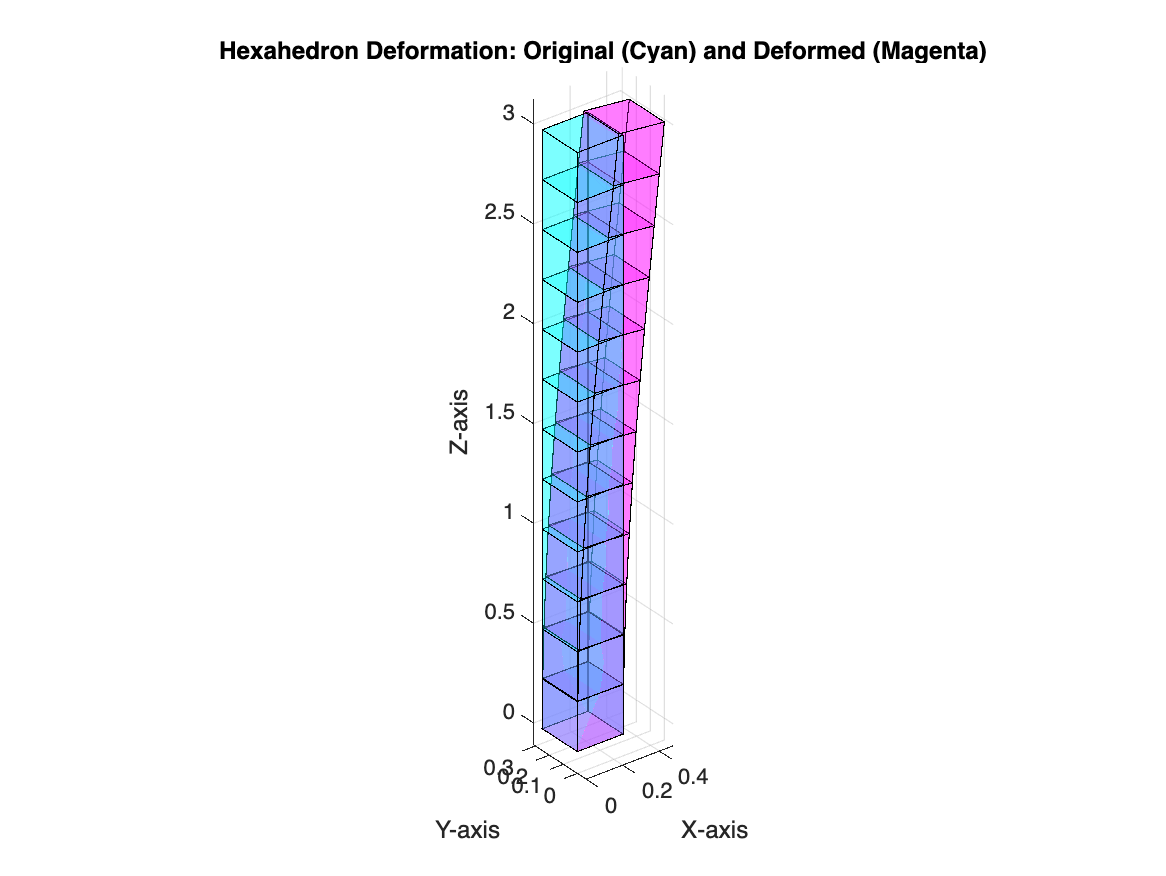


% Input data
coor = XYZCoord;             % original coordinates
nNode = size(coor,1);        % number of nodes


% Reshape displacement into matrix: [nNode x 3]
udisp_coor = reshape(uDisp, 3, [])';  % transpose to get nNode x 3

% Compute deformed coordinates
deform_coor = coor + udisp_coor;

% Define hexahedron faces (assumes standard 8-node brick element)
hexFaces = [1 2 3 4;   % bottom
            5 6 7 8;   % top
            1 2 6 5;   % side
            2 3 7 6;   % side
            3 4 8 7;   % side
            4 1 5 8];  % side

% Plotting
figure(2);
hold on

% ---------- Original Shape ----------
for e = 1:size(ELEMCon,1)
    nodes = ELEMCon(e,:);

    verts = coor(nodes, :);  % original coordinates
    for f = 1:size(hexFaces,1)
        face = hexFaces(f,:);
        patch('Vertices', verts, ...
              'Faces', face, ...
              'FaceColor', 'cyan', ...
              'FaceAlpha', 0.3, ...
              'EdgeColor', 'black');
    end
end

% ---------- Deformed Shape ----------
for e = 1:size(ELEMCon,1)
    nodes = ELEMCon(e,:);
    verts = deform_coor(nodes, :);  % deformed coordinates
    for f = 1:size(hexFaces,1)
        face = hexFaces(f,:);
        patch('Vertices', verts, ...
              'Faces', face, ...
              'FaceColor', 'magenta', ...
              'FaceAlpha', 0.3, ...
              'EdgeColor', 'black');
    end
end

xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis');
title('Hexahedron Deformation: Original (Cyan) and Deformed (Magenta)');
axis equal
view(3)
grid on
hold off

%--------Paraview Visualization of Displacement and Stress---------------%
%------This part of the code will generate the .vtk to open for viewing
%------the Displacement and Stress of the element-------------------
filename = 'model.vtk';
fid = fopen(filename, 'w');

% Header
fprintf(fid, '# vtk DataFile Version 3.0\n');
fprintf(fid, 'Model Data\n');
fprintf(fid, 'ASCII\n');
fprintf(fid, 'DATASET UNSTRUCTURED_GRID\n');

% === Write NODE COORDINATES ===
fprintf(fid, 'POINTS %d float\n', nNode);
for i = 1:nNode
    fprintf(fid, '%f %f %f\n', XYZCoord(i, :));
end

% === Write ELEMENT CONNECTIVITY ===
total_cell_size = NE * (nN + 1); % total size of CELLS array
fprintf(fid, 'CELLS %d %d\n', NE, total_cell_size);
for i = 1:NE
    fprintf(fid, '%d', nN);  % number of nodes per element
    for j = 1:nN
        fprintf(fid, ' %d', ELEMCon(i,j) - 1); % 0-based indexing for VTK
    end
    fprintf(fid, '\n');
end

% === Write CELL TYPES ===
fprintf(fid, 'CELL_TYPES %d\n', NE);
vtk_cell_code = 12; % VTK_HEXAHEDRON (use 10 for tetrahedron, 12 for hex)
for i = 1:NE
    fprintf(fid, '%d\n', vtk_cell_code);
end

% === Write POINT DATA (Displacements) ===
fprintf(fid, 'POINT_DATA %d\n', nNode);
fprintf(fid, 'VECTORS Displacement float\n');
for i = 1:nNode
    fprintf(fid, '%f %f %f\n', NODE(i).u(1), NODE(i).u(2), NODE(i).u(3));
end

% === Write CELL DATA (Stress) ===
fprintf(fid, 'CELL_DATA %d\n', NE);
fprintf(fid, 'SCALARS Stress float 1\n');
fprintf(fid, 'LOOKUP_TABLE default\n');
for i = 1:NE
    % Assuming ELEMENT(i).sigma is a scalar (e.g., von Mises)
    % You can modify this to extract scalar value if it's a matrix
    fprintf(fid, '%f\n', ELEMENT(i).sigma);
end

fclose(fid);
